
%Single spine glutamate uncaging
%assumes tseries was used to repeat stimulation of single spines, each rep
%all spines are stimulated

%clear
clearvars -except Vtimes2 voltage_norm1 voltageTraces1 voltage_norm2 voltageTraces2 voltage_norm3 voltageTraces3 voltage_norm4 voltageTraces4 voltage_norm5 voltageTraces5

alldirs=uipickfiles;
cd(char(alldirs));

% get directory name and path separately
[pathToDirName, dirName] = fileparts(char(alldirs));

%Load xml file to get info about the linescan protocol
fileName = [strcat(dirName) '.xml'];
%transform into structure
[s] = xml2struct(fileName);

%Get number of cycles
ncycle= size(s.PVScan.Sequence,2);

% load .csv data 
csvFiles = dir('**/*.csv').';

% pre-allocate cell arrays
csvNames = cell(0);
% fluoNames = cell(0);
Vtimes = cell(0);
voltageTraces = cell(0);
%currentTraces = cell(0);


%get all voltage and calcium traces
% iterate over files, collecting voltage and current data and csvNames
for csvFile = csvFiles
    try
        data = csvread(csvFile.name, 1, 0);
    catch
        %disp('Error reading .csv file. File may be empty. Skipped.');
        continue
    end

    if size(data, 2) == 3
        csvNames{end + 1} = csvFile.name(1:end-25);
        Vtimes{end + 1} = data(:, 1);
        %voltageTraces{end + 1} = data(:,2)*100; %in mV
        voltageTraces{end + 1} = smooth(data(:,2)*100,50); %in mV
        %currentTraces{end + 1} = data(:,3); %just to check amt of current inj
 else
        %disp('.csv file not in correct format. Skipped.');
    end
    
%      clear('data');    
end


ncycle = 9;

% normalize voltage Traces
for i = 1:ncycle
    base=mean(voltageTraces{i}([1:500/.05])); %%%
    voltage_norm{i} = voltageTraces{i}-base;
end
        
for i = 1:ncycle
Uncaging{i} = markpoints2([strcat(csvNames{i},'_MarkPoints') '.xml']);
end

Uniq = Uncaging{1,1}.GroupName; %names are the same for every iteration in a tseries
numGroups=length(Uniq);

Vtimes2=cell2mat(Vtimes);

% voltageTraces1=cell2mat(voltageTraces);
% voltage_norm1=cell2mat(voltage_norm);
%   voltage_normf=[voltage_norm1];
%   voltageTracesf=[voltageTraces1];
% % 
% voltageTraces2=cell2mat(voltageTraces);
% voltage_norm2=cell2mat(voltage_norm);
%     voltage_normf=[voltage_norm1,voltage_norm2];
%    voltageTracesf=[voltageTraces1,voltageTraces2];
% % % 
% voltageTraces3=cell2mat(voltageTraces);
% voltage_norm3=cell2mat(voltage_norm);
%   voltage_normf=[voltage_norm1,voltage_norm2,voltage_norm3];
%   voltageTracesf=[voltageTraces1,voltageTraces2,voltageTraces3];

% voltageTraces4=cell2mat(voltageTraces);
% voltage_norm4=cell2mat(voltage_norm);
% voltage_normf=[voltage_norm1,voltage_norm2,voltage_norm3,voltage_norm4];
% voltageTracesf=[voltageTraces1,voltageTraces2,voltageTraces3,voltageTraces4];

% voltageTraces5=cell2mat(voltageTraces);
% voltage_norm5=cell2mat(voltage_norm);
% voltage_normf=[voltage_norm1,voltage_norm2,voltage_norm3,voltage_norm4,voltage_norm5];
% voltageTracesf=[voltageTraces1,voltageTraces2,voltageTraces3,voltageTraces4,voltageTraces5];

% voltage_normf=[voltage_norm2];
% voltageTracesf=[voltageTraces2];
%        voltageTracesf(:,[4])=[];
%         voltage_normf(:,[4])=[];


for i = 1:size(voltageTracesf,2)
    x(i) = any(voltageTracesf(:,i)>-45);
end
voltageTracesf(:,x == 1) = [];
voltage_normf(:,x == 1) = [];

voltageTracesMean=mean(voltageTracesf,2);
voltage_normmean=mean(voltage_normf,2);
n=round(length(voltage_normf)/10000)

n = 10

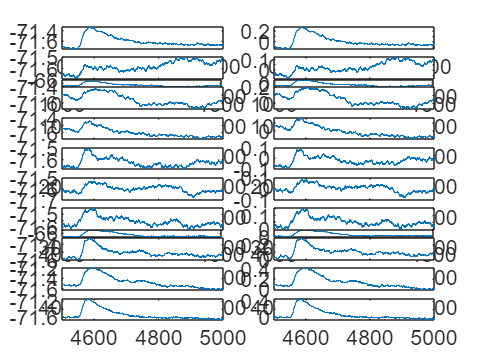


for i=1:n
    if i<n
subplot(n,2,2*i-1)
plot(Vtimes2((i-1)*10000+1:i*10000),voltageTracesMean((i-1)*10000+1:i*10000))
subplot(n,2,2*i)
plot(Vtimes2((i-1)*10000+1:i*10000),voltage_normmean((i-1)*10000+1:i*10000))
     else
      subplot(n,2,2*i-1)
        plot(Vtimes2((i-1)*10000+1:length(Vtimes2)),voltageTracesMean((i-1)*10000+1:length(voltageTracesMean)))
        subplot(n,2,2*i)
        plot(Vtimes2((i-1)*10000+1:length(Vtimes2)),voltage_normmean((i-1)*10000+1:length(voltage_normmean)))   
    end
end

%ve('ampa5.mat')%,'voltage_normmean','voltage_normf','Vtimes2')
save('nmda3.mat')%,'voltage_normmean','voltage_normf','Vtimes2')